# Tarea Semanal 7

## TS6 - M7.1

Tabla de diferencias divididas

x=[2 4 5];
y=[3 2 1];

diff(y);

difdiv2(x,y)

ans =    -0.1667
         0
         0


## TS6 - M7.2

Newtoncoeff

x= [-2 1 4 -1 3 -4]'; %vector x en columna..completar
y= [-1 2 59 4 24 -53]'; %vector y en columna..completar
a= newtoncoeff(x, y)%encuentra coef en columna...completar
s= sum(a) %almacena la suma de los coeficientes del polinomio interpolador
p= newtonpoly(a, x, 2)   %p almacena el polinomio evaluado en 2...completar

## TS6 - M7.3

Polyfit

x = [1; 2; 5; 7; 9];
y = [0.2; 2.2; 29.8; 78.2; 161.8];

p = polyfit(x,y,4);
p_6 = polyval(p, 6)

p_6 = 50.2000


syms x
g = matlabFunction((x^3+x^2-1)/5);
g_6 = g(6)

g_6 = 50.2000


error_1 = g_6 - p_6

error_1 = 7.1054e-15

p_6 =   50.199999999999996


g_6 =   50.200000000000003


error_1 =      7.105427357601002e-15


## TS6 - M7.4

Spline Natural

x = [0,1,2,3,4]
y = sin(pi/2 * x)

spline = splinenatural(x, y)

sumacoef = sum(spline(2,:))

syms z
func = matlabFunction(spline(2, 1)*((z - x(2))^3) + spline(2,2)*((z - x(2))^2) + spline(2,3)*(z - x(2)) + spline(2,4));
fvalue = func(1.5)
dfunc = diff(func, z);
dfunc = matlabFunction(dfunc);
dfvalue = dfunc(1.5)
ddfunc = diff(dfunc, z);
ddfunc = matlabFunction(ddfunc);
df2value = ddfunc(1)

## TS6 - M7.5

Brazo Robot - Spline

x = [0 2 6 7 12 15];
y = [0 4 4 6 7 1];

xx = 0:.25:15;

xx =          0    0.2500    0.5000    0.7500    1.0000    1.2500    1.5000    1.7500    2.0000    2.2500    2.5000    2.7500    3.0000    3.2500    3.5000    3.7500    4.0000    4.2500    4.5000    4.7500    5.0000    5.2500    5.5000    5.7500    6.0000    6.2500    6.5000    6.7500    7.0000    7.2500    7.5000    7.7500    8.0000    8.2500    8.5000    8.7500    9.0000    9.2500    9.5000    9.7500   10.0000   10.2500   10.5000   10.7500   11.0000   11.2500   11.5000   11.7500   12.0000   12.2500


yy = spline(x, y, xx);

yy =          0    0.9489    1.7470    2.4055    2.9357    3.3490    3.6566    3.8698    4.0000    4.0584    4.0562    4.0049    3.9157    3.7999    3.6687    3.5336    3.4057    3.2964    3.2170    3.1787    3.1929    3.2708    3.4237    3.6631    4.0000    4.4373    4.9432    5.4775    6.0000    6.4772    6.9033    7.2793    7.6062    7.8850    8.1169    8.3027    8.4436    8.5406    8.5946    8.6068    8.5780    8.5095    8.4021    8.2569    8.0750    7.8573    7.6049    7.3188    7.0000    6.6496


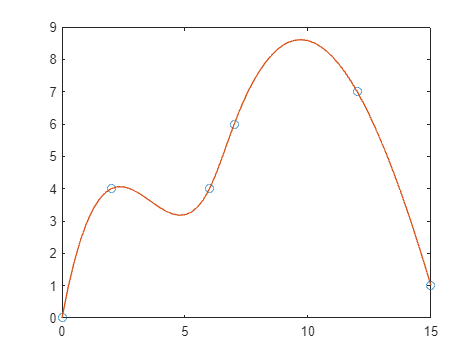


plot(x,y,'o',xx,yy)


yvalue = spline(x, y, 5)

yvalue = 3.1929

## TS7 - M8.1

Temperatura 

T = [595 623 761 849 989 1076 1146 1202 1382 1445 562]';
k = 10^20*[2.12 3.12 14.4 30.6 80.3 131 186 240 489 604 868]';

y = log(k);
n = length(T); 
col1 = ones(n,1);
col2 = log(T); 
col3 = (-1./T);

A = [col1 col2 col3]

A =    1.000000000000000   6.388561405545630  -0.001680672268908
   1.000000000000000   6.434546518787453  -0.001605136436597
   1.000000000000000   6.634633357861686  -0.001314060446781
   1.000000000000000   6.744059186311348  -0.001177856301531
   1.000000000000000   6.896694331622713  -0.001011122345804
   1.000000000000000   6.981005740721730  -0.000929368029740
   1.000000000000000   7.044032897274685  -0.000872600349040
   1.000000000000000   7.091742115095153  -0.000831946755408
   1.000000000000000   7.231287004327616  -0.000723589001447
   1.000000000000000   7.275864600546533  -0.000692041522491


M = A'*A; 
b = A'*y;
c = linsolve(M,b)

c = 1.0e+04 *

  -0.010905277461641
   0.002086739679453
  -1.484226894817199



kvalue = exp(c(1)+c(2)*log(600)-c(3)/600)

kvalue =      2.264429218272648e+21


## TS7 - M8.2

Ajuste lineal 

format long
x = [0 0 1 2 2 2];
y = [0 1 0 0 1 2];
z = [1.42 1.85 0.78 0.18 0.60 1.05];

n = 6; 
sum_xi = sum(x); 
sum_yi = sum(y);
sum_xi2 = sum(x.*x); 
sum_xiyi = sum(x.*y); 
sum_yi2 = sum(y.*y);

A = [n sum_xi sum_yi; sum_xi sum_xi2 sum_xiyi; sum_yi sum_xiyi sum_yi2]

A =      6     7     4
     7    13     6
     4     6     6



sum_zi = sum(z); 
sum_xizi = sum(x.*z); 
sum_yizi = sum(y.*z);

B = [sum_zi; sum_xizi; sum_yizi]

B =    5.879999999999999
   4.440000000000000
   4.550000000000001



coef = linsolve(A,B)

coef =    1.413255813953488
  -0.621395348837209
   0.437558139534884


a = coef(1); 
b = coef(2); 
c = coef(3);
z1 = a + b + c

z1 =    1.229418604651163


## TS7 - M8.3

format long

syms b x v a
f = (v*(b+x)-a*x)^2

$$f = {\left(v\,\left(b+x\right)-a\,x\right)}^{2}$$

deriv_a = diff(f,a)

$$deriv\_a = -2\,x\,\left(v\,\left(b+x\right)-a\,x\right)$$

deriv_b = diff(f,b)

$$deriv\_b = 2\,v\,\left(v\,\left(b+x\right)-a\,x\right)$$


x = [0.197 0.139 0.068 0.0427 0.027 0.015 0.009 0.008];
v = [21.5 21 19 16.5 14.5 11 8.5 7];

A = [sum(x.^2) -sum(x.*v); sum(x.*v) -sum(v.^2)]

A = 1.0e+03 *

   0.000065676290000  -0.009840050000000
   0.009840050000000  -1.989000000000000


b = [sum(x.^2.*v) sum(x.*v.^2)]'

b = 1.0e+02 *

   0.013722567850000
   1.970693250000000


x = linsolve(A,b)

x =   23.377620834367882
   0.016574978829171



a = x(1)

a =   23.377620834367882


b = x(2)

b =    0.016574978829171


r = 0.13

r =    0.130000000000000



aprox1=(a*r)/(b+r)

aprox1 =   20.734034776902774


## TS7 - M8.4

format long

K = [10 15 20 20]';
L = [12 18 12 15]';
F = [44.6240 66.9360 58.8818 67.3173]';

A = [log(K) log(L)]

A =    2.302585092994046   2.484906649788000
   2.708050201102210   2.890371757896165
   2.995732273553991   2.484906649788000
   2.995732273553991   2.708050201102210


b = log(F)-log(4)

b =    2.411977469765243
   2.817442577873407
   2.689237683485631
   2.823122900446537



val = linsolve(A,b);

alpha_cb = val(1);
beta_cb = val(2);

Faprox = 4*12^alpha_cb*25^beta_cb;

F = @(x) -31.0369 + (4*x^beta_cb)*(((45-3*x)/2)^alpha_cb)

F = function_handle with value:
    @(x)-31.0369+(4*x^beta_cb)*(((45-3*x)/2)^alpha_cb)



M = biseccion(F,4,8,10);

Se necesita 10 iteraciones


L = M(end,3)

L =    4.998046875000000


K = ((31.0369)/(4*L^beta_cb))^(1/alpha_cb);

TS7 - M8.4

% Definir los datos en tres vectores
P = [100, 101, 112, 122, 124, 122, 143, 152, 151, 126, 155, 159, 153, 177, 184, 169, 189, 225, 227, 223, 218, 231, 179, 240]';
L = [100, 105, 110, 117, 122, 121, 125, 134, 140, 123, 143, 147, 148, 155, 156, 152, 156, 183, 198, 201, 196, 194, 146, 161]';
K = [100, 107, 114, 122, 131, 138, 149, 163, 176, 185, 198, 208, 216, 226, 236, 244, 266, 298, 335, 366, 387, 407, 417, 431]';

A = [log(L) log(K)];

b_alpha =    0.747158411226576
   0.254349925568710


beta_aprox =    0.745650074431290


b = log(P) - log(6);

val = linsolve(A,b);

alpha_aprox = val(1)
beta_aprox = val(2)

Tabla de diff div grado 2

function delta2=difdiv2(x,y)
    n = length(x);
    M = zeros(n);
    M(1:n,1) = y;

    for k = 1:n-1
        delta_x = x(k+1:n)-x(1:n-k);
        delta_y = diff(y)./delta_x;
        M(1:n-k,k+1) = delta_y;
        y=delta_y;
    end
    
    M = [x' M];
    
    delta2 = M(:,4);
end

NewtonCoeff

function a=newtoncoeff(x,y)
%devuelve los coeficientes del polinomio de newton
    i = size(x);
    a = y(1:i(1));
    g = a;
    for k = 2:i(1)
        for j = k:i(1)
            a(j) = (g(j)-g(k-1))/(x(j)-x(k-1));
        end
        g = a;
    end
end

function p=newtonpoly(a,xdata,x)
    i = size(xdata);
    p = a(i(1));
    for k = i(1)-1:-1:1
        p = a(k) + (x-xdata(k))*p;
    end
end

Spline Natural

function S=splinenatural(X,Y)
    N=length(X)-1;
    H=diff(X);
    E=diff(Y)./H;
    diagprinc=2*(H(1:N-1)+H(2:N));
    diagsupinf=H(2:N-1);
    g0=0; gn=0;
    A=diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
    b=6*diff(E');
    g=A\b;
    g=[g0 g' gn ]
    for i=1:N
        S(i,1)=(g(i+1)-g(i))/(6*H(i));
        S(i,2)=g(i)/2;
        S(i,3)=E(i)-H(i)*(g(i+1)+2*g(i))/6;
        S(i,4)=Y(i);
        xx=linspace(X(i),X(i+1),100);
        yy=S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
        plot(xx,yy)
        hold on
    end
    grid on
    hold off
end


b

function z=biseccion(f,a,b,Maxiter)
    c=(a+b)/2;
    error=(b-a)/2;
    z=[a b c f(a) f(b) f(c) error];
    for k=1:Maxiter
        if f(a)*f(c)<0
        b=c;
        else
        a=c;
        end
        c=(a+b)/2;
        error=(b-a)/2;
        z=[z;a b c f(a) f(b) f(c) error];
    end
    [row col] = size(z);
    fprintf('Se necesita %d iteraciones\n',(row-1));
end

function [Q R]=gs_c(A)
[m n]=size(A);
Q=zeros(m,n);
R=zeros(n);
for j = 1:n
   R(1:j-1,j)=Q(:,1:j-1)'*A(:,j);
   temp=A(:,j)-Q(:,1:j-1)*R(1:j-1,j);
   R(j,j)=norm(temp);
   Q(:,j)=temp/R(j,j);
end
end

function [x]=sustireg(U,b)
[m,n]=size(U);
x=zeros(n,1);
for k=n:-1:1
    x(k)=(b(k)-sum(U(k,k+1:n)*x(k+1:n)))/U(k,k);
end
end